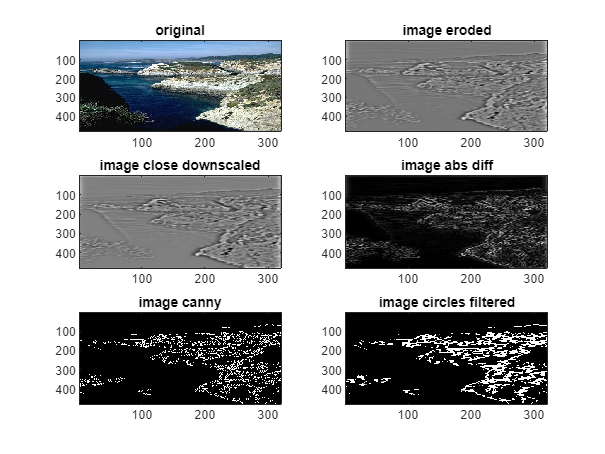

I = imread('Images/im3.jpg');
I = im2double(I);

% converion of the image to black and white from 3-channels (RGB)
image_bw = rgb2gray(I);

% Difference of Gaussian mask to enchance visible edges
dog_mask = fspecial('gaussian', 30, 1.25)-fspecial('gaussian', 30, 5.0);
image_dog = conv2(image_bw, dog_mask ,'same');

% Upscaling the DoG image by 2x for better
image_bw_upscaled = imresize(image_dog, 2, "bilinear");

% creating a 3x3 kernel (smallest) and applying it through erosion
kernel_morphology = [1 1 1; 1 1 1; 1 1 1];
image_eroded = imerode(image_bw_upscaled, kernel_morphology);

% downscaling back to the original size
image_close_downscaled = imresize(image_eroded, 0.5, "bilinear");

% subtracts each element in img1 from the corresponding element in img2
image_abs_diff = imabsdiff(image_dog, image_close_downscaled);

% This method uses two thresholds to detect strong and weak edges
image_canny = edge(image_abs_diff,'canny', 0.38, 0.46);

% This method perform  morphological thinning to reduce double lines
% generated by canny edge detector
image_morphology = bwmorph(image_canny ,'thin', Inf);

% Canny outputs a logical matrix, this converts it back to double precision
image_morphology = im2double(image_morphology);

% The following code uses Hough Circles to remove little circles created by
% canny resulting in less noise in the final image
[centers, radii, ~] = imfindcircles(image_morphology,[1 5]);
image_circles_filtered = insertShape(image_morphology,'FilledCircle', ...
                              [centers radii], Color="black", Opacity=1.0); 

% the result from insertShape will be b&w because of the original image
% however outputted as 3 channels, we convert with rgb2gray
image_circles_filtered = rgb2gray(image_circles_filtered);

% The Hough Circles code will give a warning for the selected Radius range
% of 1 to 10, stating that the algorithm will be less accurate, it is
% irrelevant, so it gets disabled
warning('off')

subplot(3,2,1); imagesc(I); colormap('default'); title('original')
subplot(3,2,2); imagesc(image_dog); colormap('gray'); title('image eroded')
subplot(3,2,3); imagesc(image_close_downscaled); colormap('gray'); title('image close downscaled')
subplot(3,2,4); imagesc(image_abs_diff); colormap('gray'); title('image abs diff')
subplot(3,2,5); imagesc(image_canny); colormap('gray'); title('image canny')
subplot(3,2,6); imagesc(image_circles_filtered); colormap('gray'); title('image circles filtered')